clear
close all
hold off


N=6; %Número de robots (a partir de N=6 buena aproximación)
iteration=500; %Número de iteraciones
step_size=0.5;
D=1; %Radio de la formación
S=10^-4*[100,1,1;1,1,0;1,0,10]; %Matriz
c0=[20;20;20]; %Posición del centro inicial (initial guess)
r0=[0 0 0]'; %Centro de contaminación
w0=1; %Movimiento circular de un radián por segundo
k=1.1;
c1=10^-4;
c2=0.6; %Parámetros para el line search

colors=["ob","ok","or","oy","og","om","oc","ob"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
pos_rob=zeros(3,N,iteration);

i=1;

Aquí se implementa el método:

while mod_rc>0.001

    if i==500
        break
    end
    grad_centr(:,i)=gradient_point_3D(c(:,i),t(i),N,D,S,w0);
    if i==1
        p=-grad_centr(:,i);
    end
    alpha1=1;
    steplengthParam=[c1,c2,alpha1,k];
    alpha(i)=alpha_strongWolfe3D(c(:,i), p, steplengthParam,t(i),N,D,S,w0);        
    c(:,i+1)=c(:,i)+alpha(i)*p;
    grad_centr(:,i+1)=gradient_point_3D(c(:,i+1),t(i),N,D,S,w0);
    beta_k1=grad_centr(:,i+1)'*(grad_centr(:,i+1)-grad_centr(:,i))/(grad_centr(:,i)'*grad_centr(:,i));   %Polak-Ribiere   
    p=-grad_centr(:,i+1)+beta_k1*p;
    %Hay un nuevo centro alrededor del cual se tienen que poner los robots
    c0=c(:,i);
    %Sacar el módulo de la diferencia entre el centro y el punto de
    %contaminación para cada iteración
    mod_r_c(i)=norm(c0-r0);
    %Para ver si va saltando el centro o es problema de la animación
 
    mod_rc=mod_r_c(i);
    i=i+1;
end
length(mod_r_c)

ans = 50

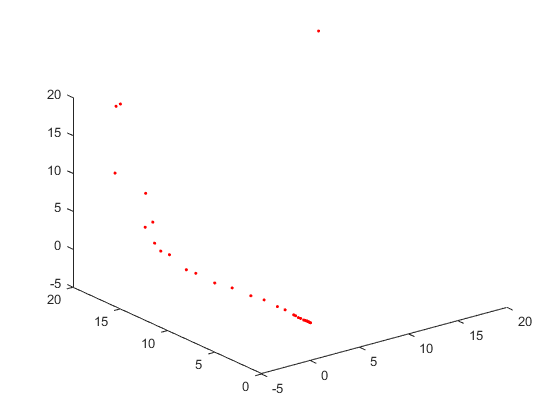

%Representación del centro
plot3(c(1,:),c(2,:),c(3,:),'.r')

hold off

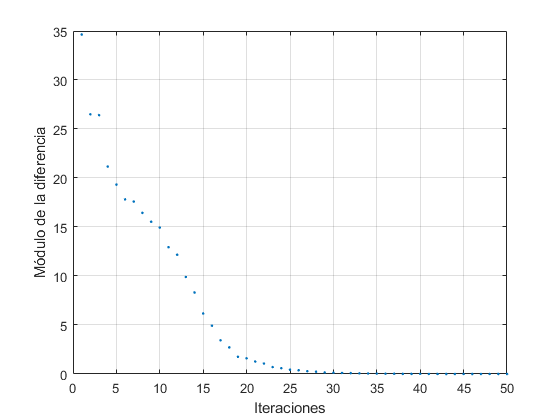

plot(1:length(mod_r_c),mod_r_c,".")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on

%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 7.7959e-04

c0

c0 = 	1.0e+-3 *

    0.0030
    0.7763
   -0.0709


iteraciones=length(mod_r_c)

iteraciones = 50